# Modelagem SIR

Vinicius Urias da Cruz RA: 20.00601-2

## Boas Práticas

clear all;
close all;
clc;


## Leitura de Dados

data = csvread('SIRpd.csv', 1);

sd = data(:,1);
id = data(:,2);
rd = data(:,3);


## Geração de Ruído

sdMedia = mean(sd)/10;
idMedia = mean(sd)/5;
rdMedia = mean(sd)/10;

sdn = rand(length(sd), 1) * sdMedia;
idn = rand(length(id), 1) * idMedia;
rdn = rand(length(rd), 1) * rdMedia;

sdNew = sd + sdn;
idNew = id + idn;
rdNew = rd + rdn;


## Exibição de Gráficos

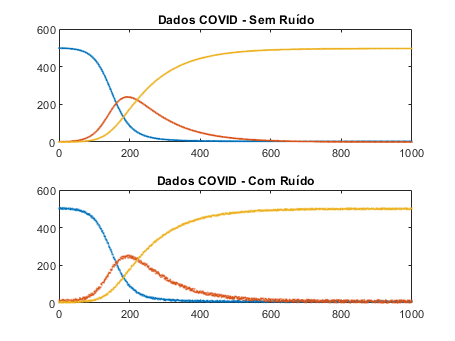

% eixo x 
tempo = linspace(0,length(sdNew),length(sdNew));
figure(1) 

% Gráfico sem ruído
subplot(2,1,1)
plot(tempo,sd, '.' , 'markersize',0.8)
hold on;
plot(tempo,id, '.' , 'markersize',0.8)
plot(tempo,rd, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Sem Ruído')

% Gráfico com ruído
subplot(2,1,2) 
plot(tempo,sdNew, '.' , 'markersize',0.8)
hold on;
plot(tempo, idNew, '.' , 'markersize',0.8)
plot(tempo, rdNew, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Com Ruído')

## Coleta de Dados Simulink

['Value'](matlab:Simulink.internal.OpenBlockParamsDialog(['ModeloSIR/beta'],'Value');)

model    = sim("ModeloSIR.slx");

SdValues = model.logsout{1}.Values.Data;
IdValues = model.logsout{2}.Values.Data;
RdValues = model.logsout{3}.Values.Data;


## Calculo do Erro

R0       = 0;
S0       = 499;
I0       = 1;
r        = 1

r = 1

beta     = 0.0001

beta = 1.0000e-03

x0       = [r beta];
X        = fminsearch(@(x) ErroQuadratico(x,sdNew,idNew,rdNew), x0)

Error using ErroQuadratico (line 19)
Inconsistent numeric values for parameter 'Value' in 'ModeloSIR/beta': Quantized parameter value (0.001) is less than minimum (1)

Error in ModelagemSIR (line 56)
X        = fminsearch(@(x) ErroQuadratico(x,sdNew,idNew,rdNew), x0)

Error in 